# Chapter 9:  Support Vector Machines

## 9.6 Lab: Support Vector Machines

### 9.6.1 Support Vector Classifier

- [fitcsvm](https://www.mathworks.com/help/stats/fitcsvm.html) - Train support vector machine (SVM) classifier for one-class and binary for low-dimensional

- [`fitclinear`](https://www.mathworks.com/help/stats/fitclinear.html)` - `Fit SVM linear classification model for two-class (binary) to high-dimensional data

- [`fitrsvm`](https://www.mathworks.com/help/stats/fitrsvm.html) - Fit a support vector machine (SVM) regression model for low-dimensional and moderate-dimensional predictor data sets

- [`fitrlinear`](https://www.mathworks.com/help/stats/fitrlinear.html) - Fit a support vector machine (SVM) regression model for high-dimensional data sets

- [`fitcecoc`](https://www.mathworks.com/help/stats/fitcecoc.html)` - `Fit multiclass models for support vector machines or other classifiers

clear all; clc; close all;
rng default; % For reproducibility
x = randn(20,2);
y = [repelem({'-1'},10), repelem({'1'},10)].';
x(strcmp('1', y),:) = x(strcmp('1', y),:) + 1;

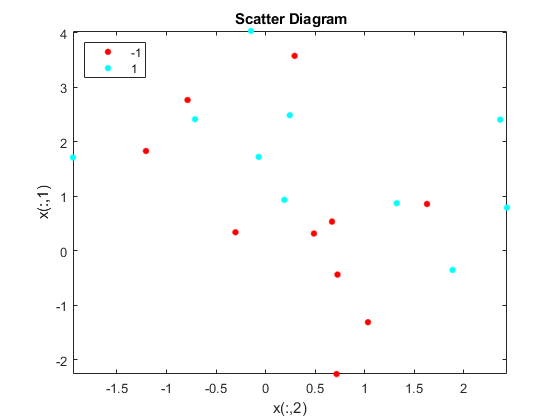

figure
gscatter(x(:,2),x(:,1),y)
title('{\bf Scatter Diagram}');
xlabel('x(:,2)'); ylabel('x(:,1)');
legend('Location','Northwest');
xlim([min(x(:,2)) max(x(:,2))]);
ylim([min(x(:,1)) max(x(:,1))])

Train an SVM classifier

svmfit = fitcsvm(x,y,'Standardize',false,'KernelFunction','linear',...
    'BoxConstraint',10);

Plot the support vector classifier obtained: 

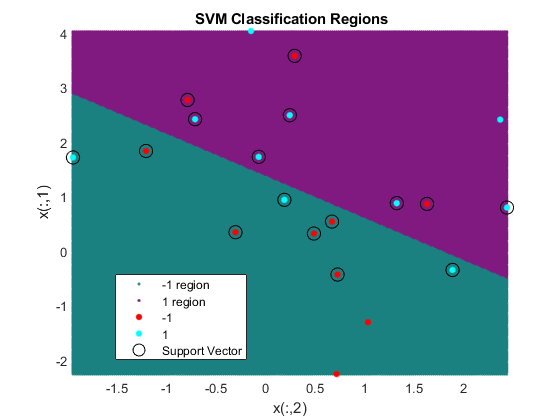

d = 0.02;
[x1Grid,x2Grid] = meshgrid(min(x(:,1)):d:max(x(:,1)),...
    min(x(:,2)):d:max(x(:,2)));
xGrid = [x1Grid(:),x2Grid(:)];
[~,score] = predict(svmfit,xGrid);
[~,maxScore] = max(score,[],2);
figure
h(1:2) = gscatter(xGrid(:,2),xGrid(:,1),maxScore,...
    [0.1 0.5 0.5; 0.5 0.1 0.5]);
hold on
h(3:4) = gscatter(x(:,2),x(:,1),y);
h(5) = plot(x(svmfit.IsSupportVector,2),...
    x(svmfit.IsSupportVector,1),'ko','MarkerSize',10);
title('{\bf SVM Classification Regions}'); xlabel('x(:,2)'); ylabel('x(:,1)');
xlim([min(x(:,2)) max(x(:,2))]); ylim([min(x(:,1)) max(x(:,1))]);
legend(h,{'-1 region','1 region','-1','1','Support Vector'},...
    'Location','best');
axis tight
hold off

Determine index of support vectors

find(svmfit.IsSupportVector == true).'

ans =      1     2     4     5     7     8     9    10    11    13    14    15    16    17    18    20


Obtain some basic information about the support vector classifier fit

svmfit

svmfit =   ClassificationSVM
             ResponseName: 'Y'
    CategoricalPredictors: []
               ClassNames: {'-1'  '1'}
           ScoreTransform: 'none'
          NumObservations: 20
                    Alpha: [16×1 double]
                     Bias: -1.0846
         KernelParameters: [1×1 struct]
           BoxConstraints: [20×1 double]
          ConvergenceInfo: [1×1 struct]
          IsSupportVector: [20×1 logical]
                   Solver: 'SMO'


  Properties, Methods


% Number of Support Vectors:
sum(svmfit.IsSupportVector)

ans = 16

% Number of Classes :
size(svmfit.ClassNames,1)

ans = 2

% Levels
svmfit.ClassNames.'

ans = 1×2 cell array
    {'-1'}    {'1'}


What if we instead used a smaller value of the cost parameter?

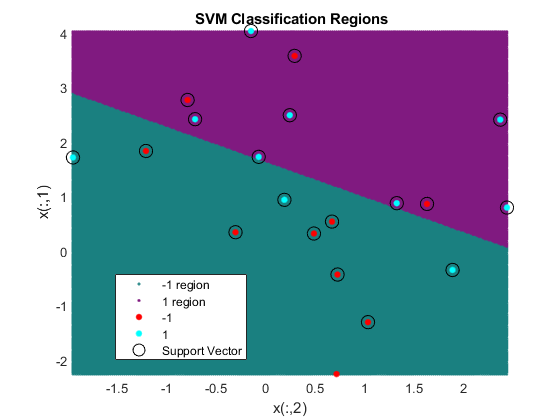

svmfit = fitcsvm(x,y,'Standardize',false,'KernelFunction','linear',...
    'BoxConstraint',0.1);
[~,score] = predict(svmfit,xGrid);
[~,maxScore] = max(score,[],2);
figure
h(1:2) = gscatter(xGrid(:,2),xGrid(:,1),maxScore,...
    [0.1 0.5 0.5; 0.5 0.1 0.5]);
hold on
h(3:4) = gscatter(x(:,2),x(:,1),y);
h(5) = plot(x(svmfit.IsSupportVector,2),...
    x(svmfit.IsSupportVector,1),'ko','MarkerSize',10);
title('{\bf SVM Classification Regions}'); xlabel('x(:,2)'); ylabel('x(:,1)');
xlim([min(x(:,2)) max(x(:,2))]); ylim([min(x(:,1)) max(x(:,1))]);
legend(h,{'-1 region','1 region','-1','1','Support Vector'},...
    'Location','best');
axis tight
hold off

find(svmfit.IsSupportVector == true).'

ans =      1     2     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20


Use cross-validation to find the optimal [`BoxConstraint`](https://www.mathworks.com/help/stats/fitcsvm.html#bt9w6j6_sep_shared-BoxConstraint) and [`KernelScale`](https://www.mathworks.com/help/stats/fitcsvm.html#bt9w6j6_sep_shared-KernelScale) parameters

VariableDescriptions = hyperparameters('fitcsvm',x,y);
% Setup the range of BoxConstraint [0.001,100]
VariableDescriptions(1).Range = [0.001,100];
% Setup the range of KernelScale [0.001,100]
VariableDescriptions(2).Range = [0.001,100];
tic
bestMod = fitcsvm(x,y,'OptimizeHyperparameters',VariableDescriptions,...
    'HyperparameterOptimizationOptions',struct('ShowPlots',false,'Verbose',0));
toc

Elapsed time is 37.967336 seconds.


fprintf('The optimal parameters of BoxConstraint and KernelScale are:\n');

The optimal parameters of BoxConstraint and KernelScale are:


bestMod.HyperparameterOptimizationResults.XAtMinEstimatedObjective

ans = 1×2 table
    BoxConstraint    KernelScale
    _____________    ___________

      0.0020664        1.1001   


% Number of Support Vectors:
sum(bestMod.IsSupportVector)

ans = 20

% Number of Classes :
size(bestMod.ClassNames,1)

ans = 2

% Levels
bestMod.ClassNames.'

ans = 1×2 cell array
    {'-1'}    {'1'}


Generate a test data set

rng default;
xtest = randn(20,2);
ytest = randsample([{'-1'}, {'1'}],20, true).';
xtest(strcmp('1', y),:) = xtest(strcmp('1', y),:) + 1;

Predict the class labels of these test observations

yPred = predict(bestMod,xtest);
confusiontable(yPred,ytest)

ans = 2×2 table
                 ytest. -1    ytest. 1
                 _________    ________

    yPred. -1        5           2    
    yPred. 1         6           7    


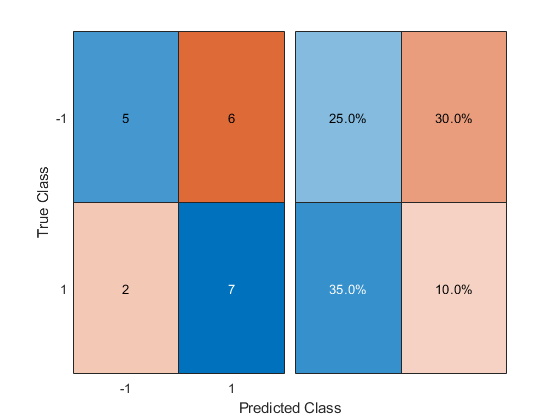

% or
confusionchart(ytest,yPred,'RowSummary','total-normalized');

Predict the class labels of these test observations if BoxConstraint = 0.1

svmfit = fitcsvm(x,y,'Standardize',false,'KernelFunction','linear',...
    'BoxConstraint',0.1);
yPred = predict(svmfit,xtest);
confusiontable(yPred,ytest)

ans = 2×2 table
                 ytest. -1    ytest. 1
                 _________    ________

    yPred. -1        8           2    
    yPred. 1         3           7    


Separate the two classes in our simulated data so that they are linearly separable:

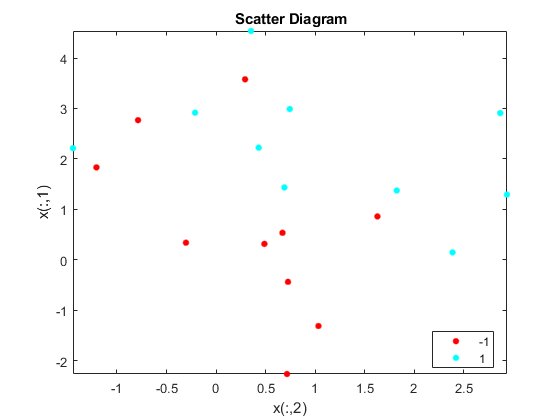

x(strcmp('1', y),:) = x(strcmp('1', y),:) + 0.5;
figure
gscatter(x(:,2),x(:,1),y)
title('{\bf Scatter Diagram}');
xlabel('x(:,2)'); ylabel('x(:,1)');
legend('Location','best');
xlim([min(x(:,2)) max(x(:,2))]);
ylim([min(x(:,1)) max(x(:,1))])

Fit the support vector classifier and plot the resulting hyperplane, using a very large value of BoxConstraint so that no observations are misclassified. 

svmfit = fitcsvm(x,y,'Standardize',false,'KernelFunction','linear',...
    'BoxConstraint',10^5);
% Number of Support Vectors:
sum(svmfit.IsSupportVector)

ans = 11

% Number of Classes :
size(svmfit.ClassNames,1)

ans = 2

% Levels
svmfit.ClassNames.'

ans = 1×2 cell array
    {'-1'}    {'1'}


Plot the support vector classifier obtained: 

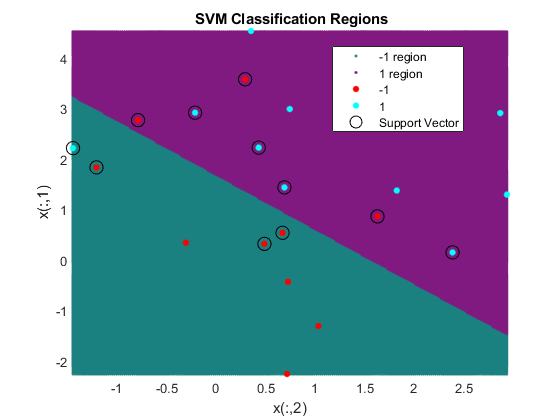

d = 0.02;
[x1Grid,x2Grid] = meshgrid(min(x(:,1)):d:max(x(:,1)),...
    min(x(:,2)):d:max(x(:,2)));
xGrid = [x1Grid(:),x2Grid(:)];
[~,score] = predict(svmfit,xGrid);
[~,maxScore] = max(score,[],2);
figure
h(1:2) = gscatter(xGrid(:,2),xGrid(:,1),maxScore,...
    [0.1 0.5 0.5; 0.5 0.1 0.5]);
hold on
h(3:4) = gscatter(x(:,2),x(:,1),y);
h(5) = plot(x(svmfit.IsSupportVector,2),...
    x(svmfit.IsSupportVector,1),'ko','MarkerSize',10);
title('{\bf SVM Classification Regions}'); xlabel('x(:,2)'); ylabel('x(:,1)');
xlim([min(x(:,2)) max(x(:,2))]); ylim([min(x(:,1)) max(x(:,1))]);
legend(h,{'-1 region','1 region','-1','1','Support Vector'},...
    'Location','best');
axis tight
hold off

BoxConstraint = 1

svmfit = fitcsvm(x,y,'Standardize',false,'KernelFunction','linear',...
    'BoxConstraint',1);
% Number of Support Vectors:
sum(svmfit.IsSupportVector)

ans = 12

% Number of Classes :
size(svmfit.ClassNames,1)

ans = 2

% Levels
svmfit.ClassNames.'

ans = 1×2 cell array
    {'-1'}    {'1'}


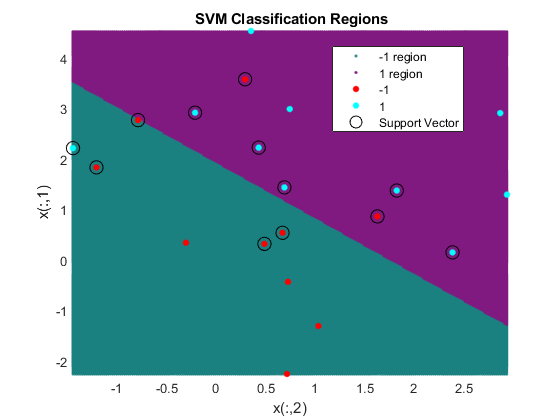

% Plot the support vector classifier obtained: 
d = 0.02;
[x1Grid,x2Grid] = meshgrid(min(x(:,1)):d:max(x(:,1)),...
    min(x(:,2)):d:max(x(:,2)));
xGrid = [x1Grid(:),x2Grid(:)];
[~,score] = predict(svmfit,xGrid);
[~,maxScore] = max(score,[],2);
figure
h(1:2) = gscatter(xGrid(:,2),xGrid(:,1),maxScore,...
    [0.1 0.5 0.5; 0.5 0.1 0.5]);
hold on
h(3:4) = gscatter(x(:,2),x(:,1),y);
h(5) = plot(x(svmfit.IsSupportVector,2),...
    x(svmfit.IsSupportVector,1),'ko','MarkerSize',10);
title('{\bf SVM Classification Regions}'); xlabel('x(:,2)'); ylabel('x(:,1)');
xlim([min(x(:,2)) max(x(:,2))]); ylim([min(x(:,1)) max(x(:,1))]);
legend(h,{'-1 region','1 region','-1','1','Support Vector'},...
    'Location','best');
axis tight
hold off

### 9.6.2 Support Vector Machine

clear all; clc; close all;

Generate some data with a non-linear class boundary

rng default; % For reproducibility
x = randn(200,2);
x(1:100,:) = x(1:100,:) + 2;
x(101:150,:) = x(101:150,:) - 2;
y = [repelem({'-1'},150), repelem({'1'},50)].';

Plotting the data makes it clear that the class boundary is indeed nonlinear: 

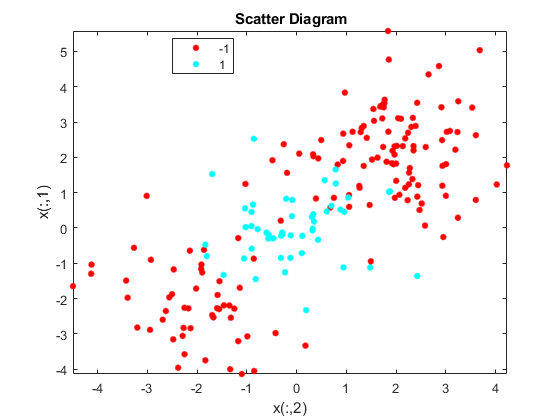

figure
gscatter(x(:,2),x(:,1),y)
title('{\bf Scatter Diagram}');
xlabel('x(:,2)'); ylabel('x(:,1)');
legend('Location','best');
xlim([min(x(:,2)) max(x(:,2))]);
ylim([min(x(:,1)) max(x(:,1))])

The data is randomly split into training and testing groups. 

rng default; % For reproducibility
cv = cvpartition(numel(y),"HoldOut",0.5);

Fit the training data using the fitcsvm() function with a radial kernel and BoxConstraint = 1: 

svmfit = fitcsvm(x(cv.training,:),y(cv.training,:),'Standardize',false,...
    'KernelFunction','rbf','BoxConstraint',1);

Plot the support vector classifier obtained: 

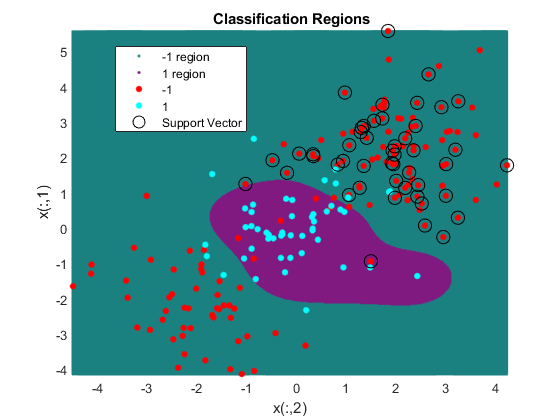

d = 0.02;
[x1Grid,x2Grid] = meshgrid(min(x(:,1)):d:max(x(:,1)),...
    min(x(:,2)):d:max(x(:,2)));
xGrid = [x1Grid(:),x2Grid(:)];
[~,score] = predict(svmfit,xGrid);
[~,maxScore] = max(score,[],2);
figure
h(1:2) = gscatter(xGrid(:,2),xGrid(:,1),maxScore,...
    [0.1 0.5 0.5; 0.5 0.1 0.5]);
hold on
h(3:4) = gscatter(x(:,2),x(:,1),y);
h(5) = plot(x(svmfit.IsSupportVector,2),...
    x(svmfit.IsSupportVector,1),'ko','MarkerSize',10);
title('{\bf Classification Regions}'); xlabel('x(:,2)'); ylabel('x(:,1)');
xlim([min(x(:,2)) max(x(:,2))]); ylim([min(x(:,1)) max(x(:,1))]);
legend(h,{'-1 region','1 region','-1','1','Support Vector'},...
    'Location','best');
axis tight
hold off

 Obtain some information about the SVM fit

% Number of Support Vectors:
sum(svmfit.IsSupportVector)

ans = 48

% Number of Classes :
size(svmfit.ClassNames,1)

ans = 2

% Levels
svmfit.ClassNames.'

ans = 1×2 cell array
    {'-1'}    {'1'}


Fit the training data using the fitcsvm() function with a radial kernel and BoxConstraint = 10^5: 

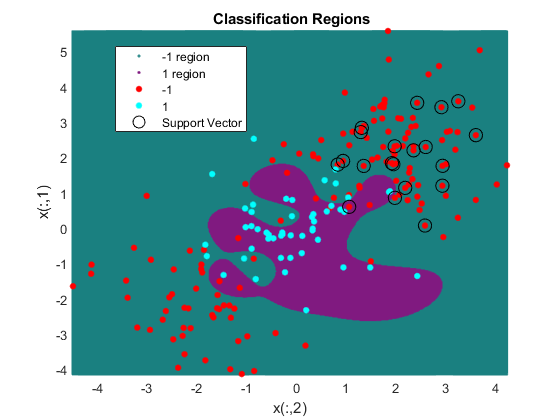

svmfit = fitcsvm(x(cv.training,:),y(cv.training,:),'Standardize',false,...
    'KernelFunction','rbf','BoxConstraint',10^5);
% Plot the support vector classifier obtained: 
d = 0.02;
[x1Grid,x2Grid] = meshgrid(min(x(:,1)):d:max(x(:,1)),...
    min(x(:,2)):d:max(x(:,2)));
xGrid = [x1Grid(:),x2Grid(:)];
[~,score] = predict(svmfit,xGrid);
[~,maxScore] = max(score,[],2);
figure
h(1:2) = gscatter(xGrid(:,2),xGrid(:,1),maxScore,...
    [0.1 0.5 0.5; 0.5 0.1 0.5]);
hold on
h(3:4) = gscatter(x(:,2),x(:,1),y);
h(5) = plot(x(svmfit.IsSupportVector,2),...
    x(svmfit.IsSupportVector,1),'ko','MarkerSize',10);
title('{\bf Classification Regions}'); xlabel('x(:,2)'); ylabel('x(:,1)');
xlim([min(x(:,2)) max(x(:,2))]); ylim([min(x(:,1)) max(x(:,1))]);
legend(h,{'-1 region','1 region','-1','1','Support Vector'},...
    'Location','best');
axis tight
hold off

Select the best choice of `BoxConstraint` and `KernelScale` for an SVM with a radial kernel:

tic
bestMod = fitcsvm(x(cv.training,:),y(cv.training,:),...
    'OptimizeHyperparameters','auto','KernelFunction','rbf',...
    'HyperparameterOptimizationOptions',struct('ShowPlots',false,'Verbose',0));
toc

Elapsed time is 47.651092 seconds.


fprintf('The optimal parameters of BoxConstraint and KernelScale are:\n');

The optimal parameters of BoxConstraint and KernelScale are:


bestMod.HyperparameterOptimizationResults.XAtMinEstimatedObjective

ans = 1×2 table
    BoxConstraint    KernelScale
    _____________    ___________

       11.743          0.49653  


View the test set predictions 

yPred = predict(bestMod,x(cv.test,:));
confusiontable(y(cv.test,:),yPred)

ans = 2×2 table
            yPred. -1    yPred. 1
            _________    ________

    . -1       71           5    
    . 1        16           8    


### 9.6.3 ROC Curves

**a) Plot ROC Curves of svmfit and bestMod for training data**

Compute the posterior probabilities (scores) of *svmfit*

Compactsvmfit = compact(svmfit);
svmfitPosterior = fitPosterior(Compactsvmfit,x(cv.training,:),y(cv.training,:));

[~,score_svmfit] = predict(svmfitPosterior,x(cv.training,:));

The last column of `score_svmfit` contains the posterior probabilities of *svmfitPosterior.ClassNames(end)* returns. Compute the standard ROC curve using the scores from the SVM model.

[X_svmfit,Y_svmfit] = perfcurve(y(cv.training,:),score_svmfit(:,end),svmfitPosterior.ClassNames(end));

Compute the posterior probabilities (scores) of *bestMod*

CompactBestMod = compact(bestMod);
bestModPosterior = fitPosterior(CompactBestMod,x(cv.training,:),y(cv.training,:));

[~,score_bestMod] = predict(bestModPosterior,x(cv.training,:));

Compute the standard ROC curve of *bestMod*

[X_bestMod,Y_bestMod] = perfcurve(y(cv.training,:),...
    score_bestMod(:,end),bestModPosterior.ClassNames(end));

Plot the ROC curves on the same graph.

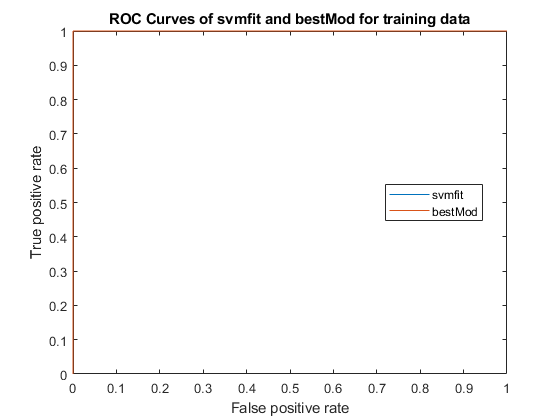

plot(X_svmfit,Y_svmfit);
hold on
plot(X_bestMod,Y_bestMod);
legend('svmfit','bestMod','Location','Best')
xlabel('False positive rate'); ylabel('True positive rate');
title('ROC Curves of svmfit and bestMod for training data');
hold off

**b) Plot ROC Curves of svmfit and bestMod for test data**

Compute the posterior probabilities (scores) of *svmfit*

Compactsvmfit = compact(svmfit);
svmfitPosterior = fitPosterior(Compactsvmfit,x(cv.test,:),y(cv.test,:));
[~,score_svmfit] = predict(svmfitPosterior,x(cv.test,:));

Compute the standard ROC curve using the scores from the SVM model.

[X_svmfit,Y_svmfit] = perfcurve(y(cv.training,:),score_svmfit(:,end),svmfitPosterior.ClassNames(end));

Compute the posterior probabilities (scores) of *bestMod*

CompactBestMod = compact(bestMod);
bestModPosterior = fitPosterior(CompactBestMod,x(cv.test,:),y(cv.test,:));
[~,score_bestMod] = predict(bestModPosterior,x(cv.test,:));

Compute the standard ROC curve of *bestMod*

[X_bestMod,Y_bestMod] = perfcurve(y(cv.training,:),...
    score_bestMod(:,end),bestModPosterior.ClassNames(end));

Plot the ROC curves on the same graph.

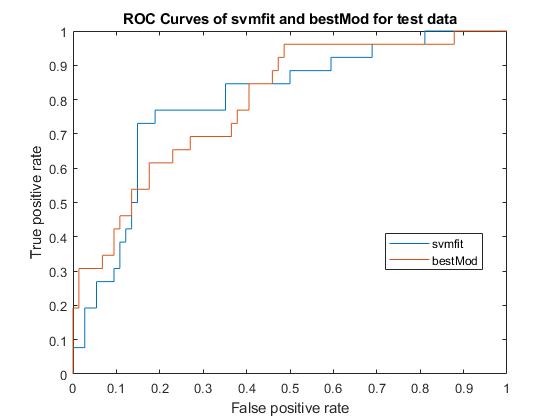

plot(X_svmfit,Y_svmfit);
hold on
plot(X_bestMod,Y_bestMod);
legend('svmfit','bestMod','Location','Best')
xlabel('False positive rate'); ylabel('True positive rate');
title('ROC Curves of svmfit and bestMod for test data');
hold off

### 9.6.4 SVM with Multiple Classes

[Fit multiclass models for support vector machines or other classifiers](https://www.mathworks.com/help/stats/fitcecoc.html)

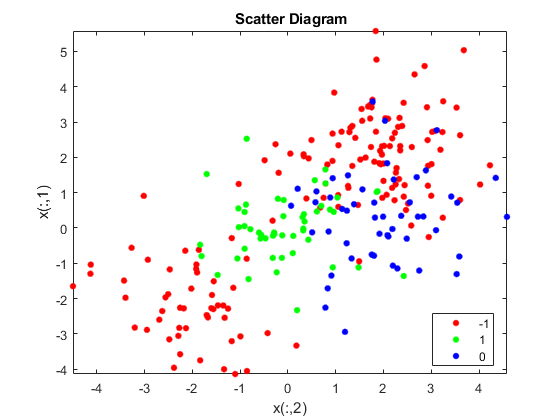

rng default; % For reproducibility
x = [x; randn(50,2)];
y = [y; repelem({'0'},50).'];
x(strcmp(y,'0'),2) = x(strcmp(y,'0'),2) + 2;
figure
gscatter(x(:,2),x(:,1),y);
title('{\bf Scatter Diagram}');
xlabel('x(:,2)'); ylabel('x(:,1)');
legend('Location','best');
xlim([min(x(:,2)) max(x(:,2))]);
ylim([min(x(:,1)) max(x(:,1))]);

Fit an SVM to the data:

template = templateSVM('Standardize',false,'KernelFunction','rbf','BoxConstraint',10,'KernelScale',1);
svmfit = fitcecoc(x,y,'Learners',template,'FitPosterior',true);

Define a grid of values in the observed predictor space. Predict the posterior probabilities for each instance in the grid.

xMax = max(x);
xMin = min(x);
x1Pts = linspace(xMin(1),xMax(1));
x2Pts = linspace(xMin(2),xMax(2));
[x1Grid,x2Grid] = meshgrid(x1Pts,x2Pts);

Predict the sample class posterior probabilities

[~,~,~,PosteriorRegion] = predict(svmfit,[x1Grid(:),x2Grid(:)]);

Associate each new observation with the classifier that gives it the maximum score.

[~,maxScore] = max(PosteriorRegion,[],2);

Color in the regions of the plot based on the class to which the corresponding new observation belongs.

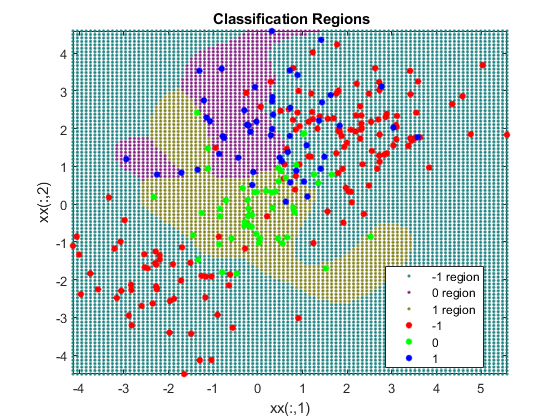

figure
h(1:3) = gscatter(x1Grid(:),x2Grid(:),maxScore,...
    [0.1 0.5 0.5; 0.5 0.1 0.5; 0.5 0.5 0.1]);
hold on
h(4:6) = gscatter(x(:,1),x(:,2),y);
title('{\bf Classification Regions}');
xlabel('xx(:,1)');
ylabel('xx(:,2)');
legend(h,{'-1 region','0 region','1 region',...
    '-1','0','1'},...
    'Location','best');
axis tight
hold off

### 9.6.5 Application to Gene Expression Data

clear all; clc; close all;
Khan_xtest = readtable('Data\Khan_xtest.csv','ReadRowNames', true);
Khan_xtrain = readtable('Data\Khan_xtrain.csv','ReadRowNames', true);
Khan_ytest = readtable('Data\Khan_ytest.csv','ReadRowNames', true);
Khan_ytrain = readtable('Data\Khan_ytrain.csv','ReadRowNames', true);

size(Khan_xtrain)

ans =           63        2308


size(Khan_xtest)

ans =           20        2308


height(Khan_ytrain)

ans = 63

height(Khan_ytest)

ans = 20

summary(categorical(Khan_ytrain.x))

     1       8 
     2      23 
     3      12 
     4      20 


summary(categorical(Khan_ytest.x))

     1      3 
     2      6 
     3      6 
     4      5 


rng default % For reproducibility

Create an SVM template. Standardize the predictors, and specify the linear kernel.

template = templateSVM('Standardize',true,'KernelFunction','linear');
out = fitcecoc(Khan_xtrain,Khan_ytrain.x,'Learners',template,'FitPosterior',true);

Predict the label for training

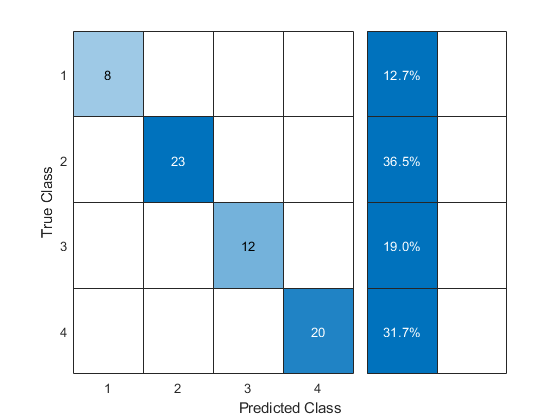

[labelKhan_xtrain,~,~,~] = resubPredict(out);
confusionchart(Khan_ytrain.x,labelKhan_xtrain,'RowSummary','total-normalized');

Predict the label for test

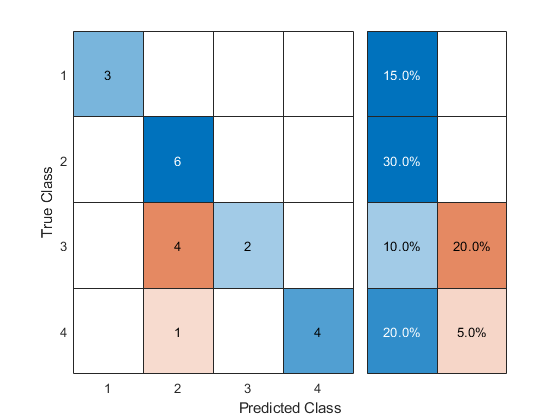

[labelKhan_xtest,~,~,~] = predict(out, Khan_xtest);
confusionchart(Khan_ytest.x,labelKhan_xtest,'RowSummary','total-normalized');

Find parameters of the optimal model

rng default
tic
outBest = fitcecoc(Khan_xtrain,Khan_ytrain.x,'OptimizeHyperparameters','auto',...
    'HyperparameterOptimizationOptions',struct('AcquisitionFunctionName',...
    'expected-improvement-plus','ShowPlots',false,'Verbose',0));
toc

Elapsed time is 227.138973 seconds.


Predict the label in training data for optimal model

labelKhan_xtrain = resubPredict(outBest);
confusionchart(Khan_ytrain.x,labelKhan_xtrain,'RowSummary','total-normalized');

Predict the label in test data for optimal model

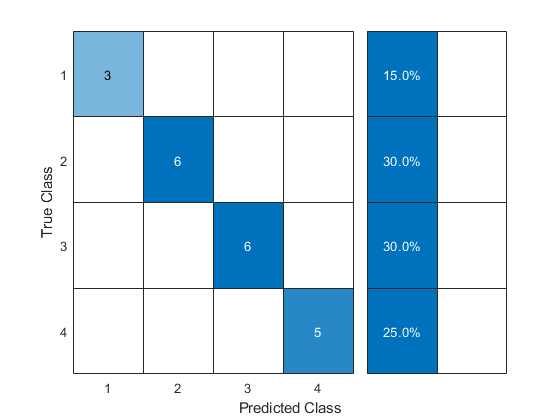

labelKhan_xtest = predict(outBest, Khan_xtest);
confusionchart(Khan_ytest.x,labelKhan_xtest,'RowSummary','total-normalized');